# PCC Index vs. Em

## Extract Spacecraft data

% Extract error and X pdf from data
dataFolder = 'G:\My Drive\Research\Projects\Data\omni_components\';
geotail1 = extract_set_of_data(dataFolder,'geotail');
wind1 = extract_set_of_data(dataFolder,'wind');
ace1 = extract_set_of_data(dataFolder,'ace');

% ACE, WIND, GEOTAIL, time conjunctions
[~,~,wi]=intersect(geotail1.datetime,wind1.datetime);
[~,ai,wii]=intersect(ace1.datetime,wind1.datetime(wi));
[~,gi,~]=intersect(geotail1.datetime,wind1.datetime(wi(wii)));
% wi = wi(wii);

% ACE, WIND, GEOTAIL conjunction tables
ace = ace1(ai,:);
wind = wind1(wi,:);
geotail = geotail1(gi,:);


## PCC Simple Saturation Model

Stauning P, 2012, Section 5.2; provides a model of polar cap index saturation with geoeffective field $E_m$. $PCC = \frac{E_m}{\sqrt{1+(E_m/E_0)^2}}; E_0 = 10.5 mV/m
$

PCCm = @(E,E_0) E./(sqrt(1+(E./E_0).^2));

## Extract PCC/PCN/PCS

From [https://pcindex.org/](https://pcindex.org/) , from 1995 to 2018


$$PCC = [(PCN \ if >0 \ or \ else\  0) + (PCS\ if\ >0\ or\ else\ 0)]/2$$


The  PCC  indices  have  been  preferred  over  the  hemispheric  PCN  or  PCS  indices since possible saturation effects are globally extended. From the scatter plot in Fig. 7 the  saturation  effect  is  evident. (Stauning, 2012)

polarCapDataFolder = 'G:\My Drive\Research\Projects\Data\pc_index\PCI\';
pci = extract_set_of_data_PCI(polarCapDataFolder);
pci.PCN(pci.PCN>=999)=nan;
pci.PCS(pci.PCS>=999)=nan;
temp.PCN=pci.PCN;
temp.PCS=pci.PCS;
temp.PCN(temp.PCN<=0)=0;
temp.PCS(temp.PCS<=0)=0;
pci.PCC = 0.5.*(temp.PCN + temp.PCS); % Calculating PCC from PCN and PCS
 

Select the conjugate time instants of WIND and PCC index. A constant offset in time between the two does not seem to make any major difference in the results. 

[~,piIII,wiIII]=intersect(pci.datetime+minutes(0),wind1.datetime);
pci4 = pci(piIII,:);
wind4 = wind1(wiIII,:);

Calculating $<PCC|X^*_{Wind}>$

XBins = 0:1:30;
XPCC = wind4.E_kl.*10^-3;
PCC = pci4.PCC;
EPCCgW = create_curve(XPCC,PCC,XBins);

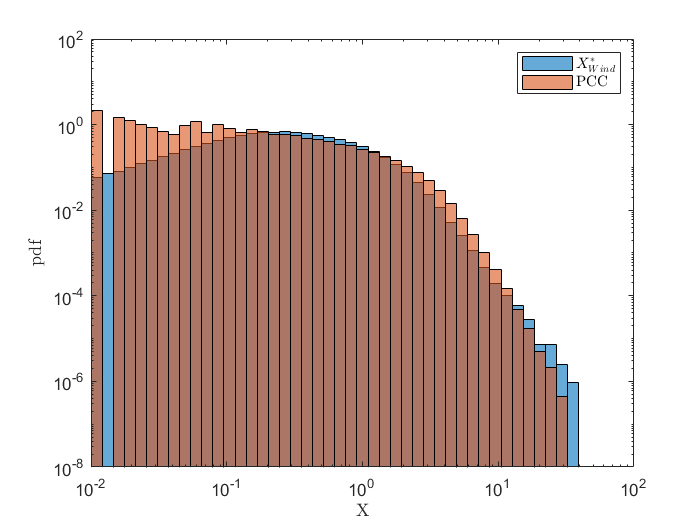

figure; 
xBinLog=logspace(-2,2,50);
histogram(XPCC,xBinLog,'Normalization','pdf');
hold on;
histogram(PCC,xBinLog,'Normalization','pdf');
set(gca,'YScale','log','XScale','log');
xlabel('X');
ylabel('pdf');
legend('$X^*_{Wind}$','PCC','Interpreter','latex');

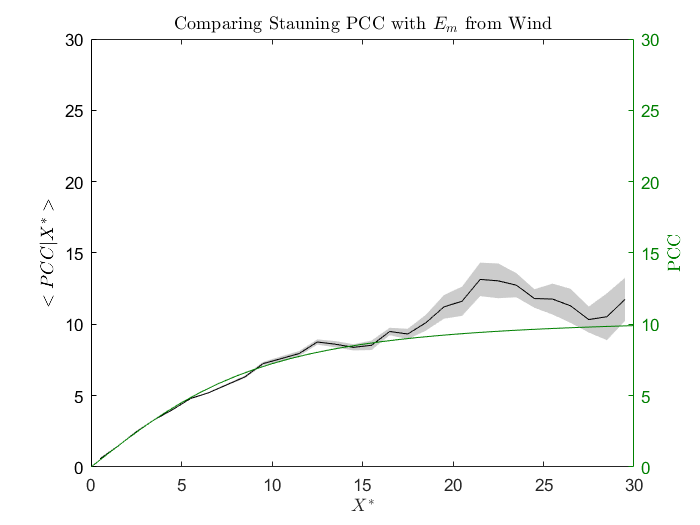

figure;
yyaxis left
p1 = plot_curve(EPCCgW,'k');
ylim([0,30]);
set(gca,'ycolor','k');
ylabel('$<PCC|X^*>$');

yyaxis right
plot(XBins,PCCm(XBins,10.5),'Color',[0 0.5 0]);
ylim([0,30]);
xlabel('$X^*$');
ylabel('PCC');
set(gca,'ycolor',[0 0.5 0]);

title('Comparing Stauning PCC with $E_m$ from Wind');

Calculating Error between PCC and $X_{\left\lbrace \mathrm{Wind}\right\rbrace }^{\;*}$

e2 = XPCC - PCC; 
eNorm2 = e2./PCC;
[Pe2gX,XPe2gX,YPe2gX] = conditional_pdf(eNorm2(:),PCC(:),-5:0.1:5,0:1:20);

fig=figure;
resize_figure(fig,150,150);
tiledlayout(1,1,'TileSpacing',"loose");
nexttile
plot_2D_error(XPe2gX, YPe2gX, Pe2gX,'$P(X^*-X|X)$');

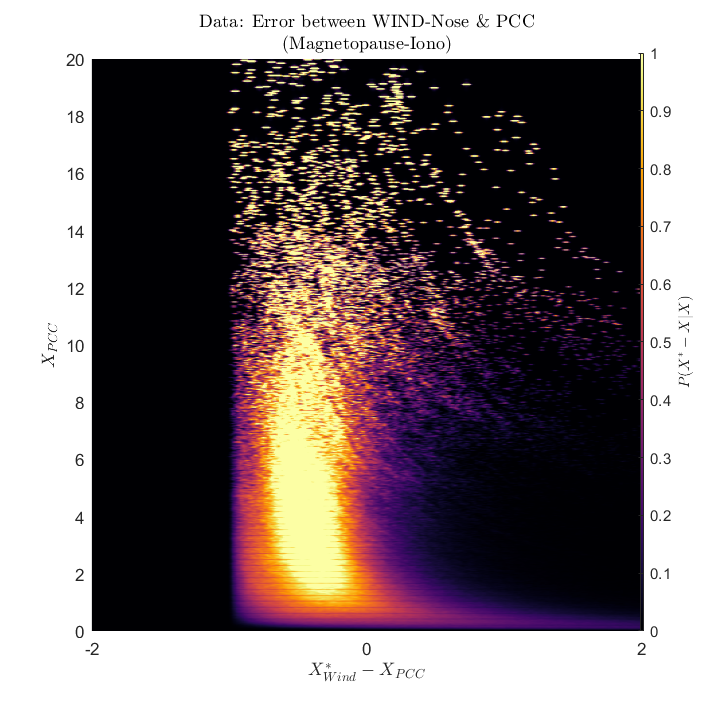

caxis([0,1]);
xlabel('$X^*_{Wind}-X_{PCC}$','Interpreter','latex');
ylabel('$X_{PCC}$');
title({'Data: Error between WIND-Nose \& PCC','(Magnetopause-Iono)'},'Interpreter','latex');
xlim([-2,+2]);
colormap(inferno);
set(gca,'XTick',[-4,-2,0,2,4]);

Plotting standard deviation with X

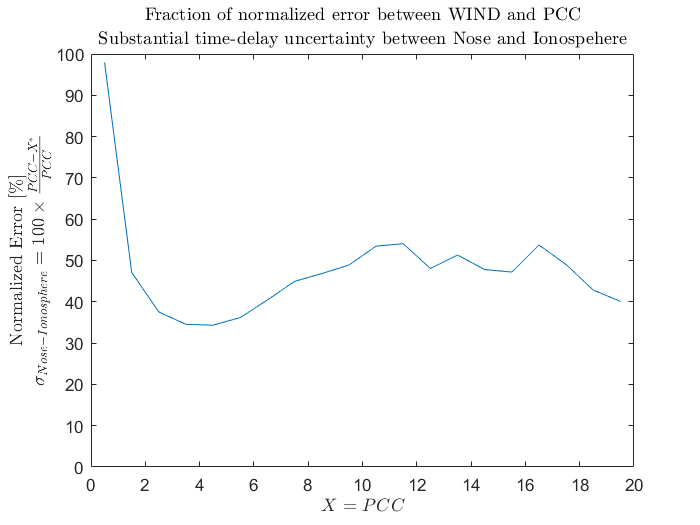

XBins1 = 0:1:20;
EegPCC = create_curve(PCC(:),e2(:),XBins1);
figure; 
xMid = XBins1(1:end-1)+0.5;
plot(xMid, 100.*EegPCC.stdYgX./xMid);
ylim([0,100]);
xlabel('$X=PCC$');
ylabel({'Normalized Error [\%]', '$\sigma_{Nose-Ionosphere}=100 \times \frac{PCC-X^*}{PCC}$'});
title('Fraction of normalized error between WIND and PCC','Substantial time-delay uncertainty between Nose and Ionospehere')

## Attempt at Regression Calibration

% mu_logw = nanmean(log(XPCC(XPCC>0)));
% s_logw = nanstd(log(XPCC(XPCC>0)));
% s_u = nanmean(eNorm2(eNorm2~=inf)); 
% % lambda = (s_logw.^2 - s_u.^2)./s_logw.^2;
% lambda = var(log(PCC(PCC>0)))./var(log(XPCC(XPCC>0)));
% alpha = (mu_logw).*(1-lambda)+0.5.*s_u.^2;
% figure;
% plot(XBins,XBins.^lambda.*exp(alpha + 0.5.*lambda.*s_u.^2));

## Extract CPCP

Walach send this database of cross-polar cap potential (~PCN index) derived from 

polarCapData = 'G:\My Drive\Research\Projects\Data\pc_index\CPCP_n_limit300.txt';
superDarn = extract_CPCP(polarCapData);
[~,siI,wiI]=intersect(superDarn.datetime+minutes(0),wind1.datetime);
superDarn2 = superDarn(siI,:);
wind2 = wind1(wiI,:);

Based  on  SuperDARN  radar  measurements  Fiori  et  al.  (2009)  derived  a  similar  relation  between ΦPC and the PCN index: $\Phi_{PC}\approx  35 + 12 PCN [kV]$. 

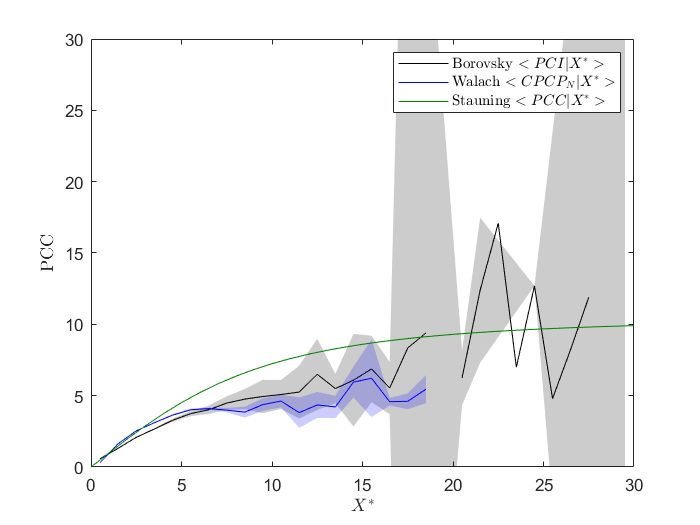

XBins = 0:1:30;
XCPCP = wind2.E_kl(:).*10^-3;
CPCP = (superDarn2.PCPC(:)-35)./12; %[PCI and PCN index relationship from SuperDarn, 
CPCP1 = (superDarn2.PCPC(:)-38.20)./16.22; %[PCI and PCN index relationship from SuperDarn, 
EPCgW = create_curve(wind2.E_kl(:).*10^-3,CPCP,XBins);
EPC1gW = create_curve(wind2.E_kl(:).*10^-3,CPCP1,XBins);
figure;
p1 = plot_curve(EPCIgW,'k');
hold on;
p2 = plot_curve(EPCgW,'b'); 
hold on;
% p21 = plot_curve(EPC1gW,'c');
% hold on;
p3=plot(XBins,PCCm(XBins,10.5),'Color',[0 0.5 0]);
ylim([0,30]);
xlabel('$X^*$');
ylabel('PCC');
legend([p1,p2,p3],'Borovsky $<PCI|X^*>$','Walach $<CPCP_N|X^*>$','Stauning $<PCC|X^*>$','Interpreter','latex');

## Error between CPCP and Em

e = XCPCP - CPCP1; 
eNorm = e./CPCP1;

[PegX,XPegX,YPegX] = conditional_pdf(eNorm(:),CPCP(:),-5:0.1:5,0:1:20);

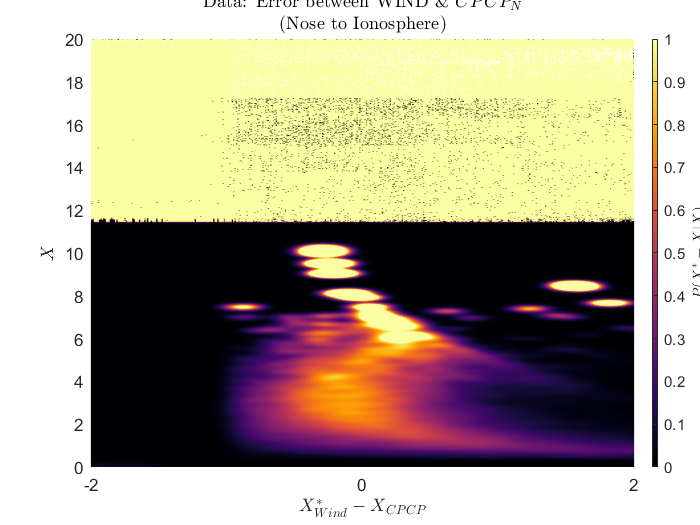

figure;
colormap(inferno);
plot_2D_error(XPegX, YPegX, PegX,'$P(X^*-X|X)$');
caxis([0,1]);
xlabel('$X^*_{Wind}-X_{CPCP}$','Interpreter','latex');
ylabel('$X$');
title({'Data: Error between WIND \& $CPCP_N$','(Nose to Ionosphere)'},'Interpreter','latex');
xlim([-2,+2]);
set(gca,'XTick',[-4,-2,0,2,4]);

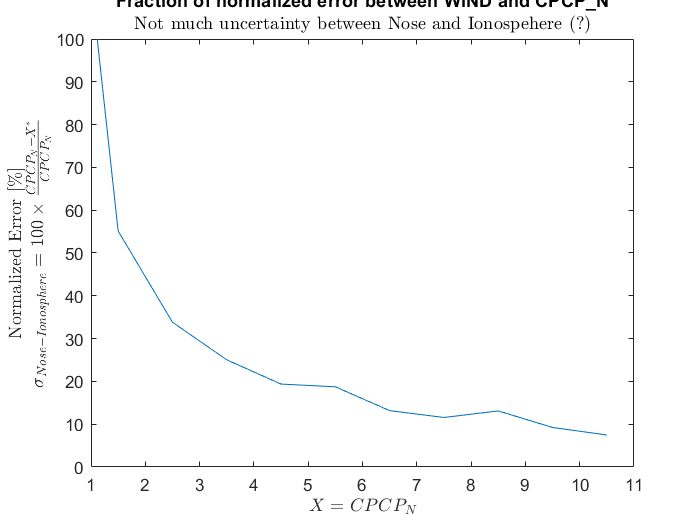

XBins1 = 0:1:11;
EegXCPCP = create_curve(XCPCP(:),e(:),XBins1);
figure; 
xMid = XBins1(1:end-1)+0.5;
plot(xMid, 100.*EegXCPCP.stdYgX./xMid);
ylim([0,100]);
xlabel('$X=CPCP_N$');
ylabel({'Normalized Error [\%]', '$\sigma_{Nose-Ionosphere}=100 \times \frac{CPCP_N-X^*}{CPCP_N}$'});
title('Fraction of normalized error between WIND and CPCP_N','Not much uncertainty between Nose and Ionospehere (?)','Interpreter',"latex");

## Extract PCI

### From Borovsky & Denton, (2012)

Here $X^*$ = WIND measurements of $E_m$, and $X$ = PCI.

Below we select the conjugate time instants of WIND and PCI index from Borovsky database. 

inputFileStr='G:\My Drive\Nithin\Job Search\JEPostDoc\Data\2018ja025430-sup-0001-data_set_si-s01.txt';
borovsky = readtable(inputFileStr);

borovsky.Properties.VariableNames...
    ([5,6,7,8,9,10,11,12,13,14,15,16,17,18])...
    = {'S1','E1','E1_E1pred','AL','AU','PCI',...
    'Kp','am','Dst','mPe','mPi','Pips',...
    'Fe130','Ssince'};
borovsky.datetime = datetime(borovsky.year,1,borovsky.day,borovsky.hr,0,0,0);
[~,biII,wiII]=intersect(borovsky.datetime,wind1.datetime);
borovsky3 = borovsky(biII,:);
wind3 = wind1(wiII,:);

Calculating $<PCI|X^*_{Wind}>$

XBins = 0:1:30;
PCI = borovsky3.PCI(:)+1.029; % Adding mean of PCI that was substracted in the database
XPCI = wind3.E_kl(:).*10^-3;
EPCIgW = create_curve(XPCI,PCI,XBins); % Creating E(PCI|X*)

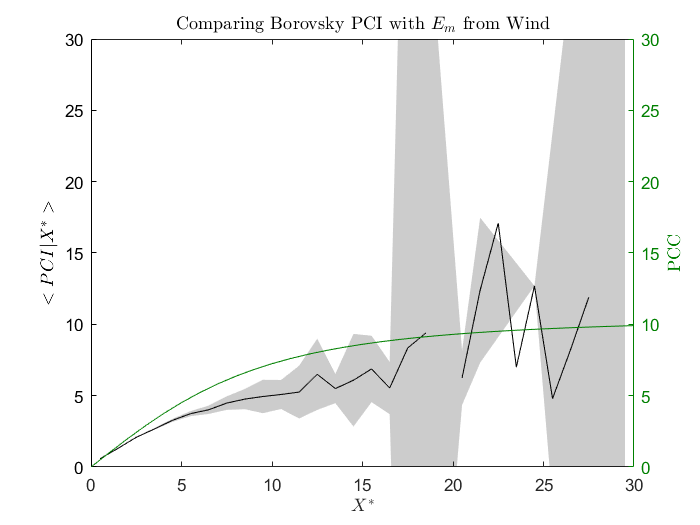

set(0,'defaulttextInterpreter','latex');

figure;

yyaxis left
p1 = plot_curve(EPCIgW,'k');
ylim([0,30]);
set(gca,'ycolor','k');
ylabel('$<PCI|X^*>$');
yyaxis right

plot(XBins,PCCm(XBins,10.5),'Color',[0 0.5 0]);
ylim([0,30]);
xlabel('$X^*$');
ylabel('PCC');
set(gca,'ycolor',[0 0.5 0]);

title('Comparing Borovsky PCI with $E_m$ from Wind');

## Error between PCI and Em

e1 = XPCI - PCI; 
eNorm1 = e1./PCI;
[Pe1gX,XPe1gX,YPe1gX] = conditional_pdf(eNorm1(:),PCI(:),-5:0.1:5,0:1:20);

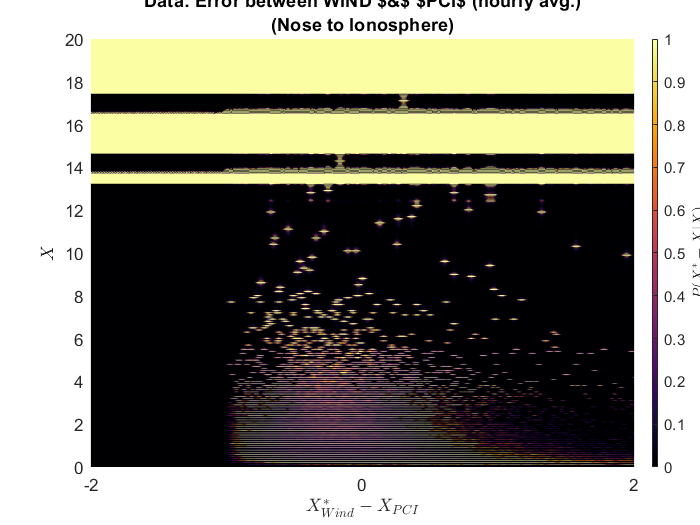

figure;
colormap(inferno);
plot_2D_error(XPe1gX, YPe1gX, Pe1gX,'$P(X^*-X|X)$');
caxis([0,1]);
xlabel('$X^*_{Wind}-X_{PCI}$','Interpreter','latex');
ylabel('$X$');
title({'Data: Error between WIND $&$ $PCI$ (hourly avg.)','(Nose to Ionosphere)'},'Interpreter','latex');
xlim([-2,+2]);
set(gca,'XTick',[-4,-2,0,2,4]);

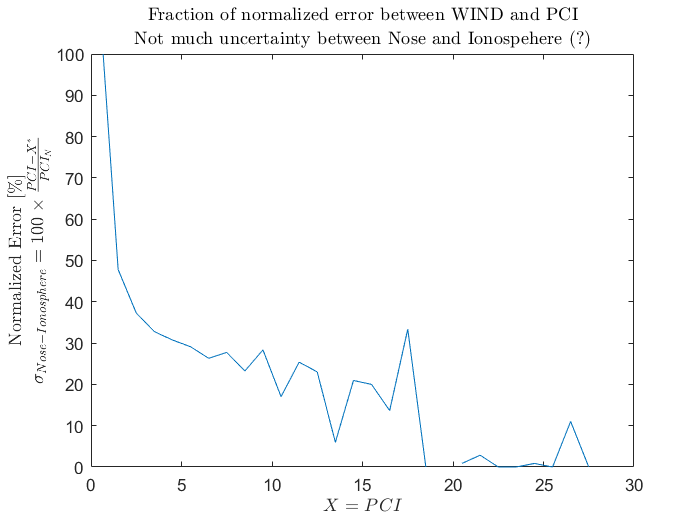

XBins = 0:1:30;
Ee1gXPCI = create_curve(XPCI(:),e1(:),XBins);
figure; 
xMid = XBins(1:end-1)+0.5;
plot(xMid, 100.*Ee1gXPCI.stdYgX./xMid);
ylim([0,100]);
xlabel('$X=PCI$');
ylabel({'Normalized Error [\%]', '$\sigma_{Nose-Ionosphere}=100 \times \frac{PCI-X^*}{PCI_N}$'});
title('Fraction of normalized error between WIND and PCI','Not much uncertainty between Nose and Ionospehere (?)','Interpreter',"latex");

## Functions

function [edges, value] = create_segmented_pdfs(X,Y,XBins,XSegments,normalizationStr)

if nargin<5
    normalizationStr = 'countdensity';
end

value = zeros(length(XSegments),length(XBins)-1);
for i=1:1:length(XSegments)
    if i==1
        [value(i,:),edges] = histcounts(Y(X<=XSegments(i)),XBins,'Normalization',normalizationStr);
%         edges = hh.BinEdges(2:end) - (hh.BinEdges(2)-hh.BinEdges(1))/2;
        edges = edges(2:end) - (edges(2)-edges(1))/2;
%         edges = edges(1:end-1);
    elseif i>1 && i < length(XSegments)
        value(i,:) = histcounts(Y(X>XSegments(i-1) & X<=XSegments(i)),XBins,'Normalization',normalizationStr);
    else
       value(i,:) = histcounts(Y(X>=XSegments(i-1)),XBins,'Normalization',normalizationStr);
    end
    
%     value(i,:) = hh.Values; 
end

end


function p = plot_curve(curve, color)

CI1 = interp_nans(curve.CI);
p=plot(curve.XBins, curve.YgX,color);
hold on;
plot_ci(curve.XBins,CI1,color,0.2);
end

function plot_ci(x,ci,color,alpha)
    hold on;
    X2 = [x, fliplr(x)];
    inBetween = [ci(:,1)', fliplr(ci(:,2)')];
    fill(X2,inBetween,color,'LineStyle','none','FaceAlpha',alpha);
end

function p = plot_2D_error(Y,X,P,yLabel)
    p = pcolor(Y,X,P);
    set(p,'EdgeColor','none');
    colorbar_thin('YLabel',yLabel);
end

function curve = create_curve(X, Y, Ei)

if nargin<3
    Ei = 100;
end
Y = Y(:);
Y(Y==999999)=nan;

X1 = X(~isnan(X) & ~isnan(Y));
Y1 = Y(~isnan(X) & ~isnan(Y));
X = X1;
Y = Y1;

[xindx, E] = discretize(X(:),Ei);

for i = 1:max(xindx)
    curve.YgX(i) = nanmean(Y(xindx==i));
    curve.stdYgX(i) = nanstd(Y(xindx==i));
    curve.NSamples(i) = sum(xindx==i & ~isnan(Y));
    curve.SEM(i) = nanstd(Y(xindx==i))./sqrt(curve.NSamples(i));
    curve.ts(i,:) = tinv([0.025 0.975],curve.NSamples(i)-1);
    curve.CI(i,:) = curve.YgX(i) + curve.ts(i,:)*curve.SEM(i);
    curve.XBins(i) = 0.5*(E(i)+E(i+1));
end

curve.E = E; 

end

function [fXgY,XX,YY] = conditional_pdf(X, Y, gridx, gridy)

X1 = X(~isnan(X) & ~isnan(Y));
Y1 = Y(~isnan(X) & ~isnan(Y));
X = X1;
Y = Y1;

sz = 2^10;
Y = Y(:);
Y(Y==999999)=nan;

[bandwidth,fXY,XX,YY]=kde2d([X,Y],sz,[min(gridx),min(gridy)],[max(gridx),max(gridy)]);
[fY, YY1] = ksdensity(Y,YY(:,1));

fXgY = fXY./repmat(fY,1,sz);

% [XX, YY] = meshgrid(gridx,gridy);
% 
% [fxy, yii] = ksdensity([X,Y],[XX(:),YY(:)]);
% Fxy = scatteredInterpolant(yii(:,1),yii(:,2),fxy);
% 
% [fy, yi] = ksdensity(Y,gridy);
% Fy = griddedInterpolant(yi,fy);
% 
% cpdf = Fxy(XX,YY)./(Fy(gridy)')./(sum((Fxy(XX,YY)./(Fy(gridy)')),2));

end


function [M, nSample, nEnsemble]= split_series(series,sampleSize,MaxNoOfMissingValues)
    if nargin<3
        MaxNoOfMissingValues=1000;
    end
        
    series = padarray(series,sampleSize-mod(length(series),sampleSize),'post');
    L = length(series); 
    M0 = reshape(series,sampleSize,[])';
    indx=sum(isnan(M0),2)>MaxNoOfMissingValues;
    l = 1:1:size(M0,1);
    k=1;
    for i=l(~indx)
        M(k,:) = M0(i,:);
        k=k+1;
    end
    nSample = size(M,2);
    nEnsemble = size(M,1);
    
    M = interp_nans(M')';
    
%     M = M-mean(M,2);
end

function [RArray,lag]=find_correlation(M,nSample,nEnsemble,sampleTime)
    dt = sampleTime;
    lag = fftshift(-nSample:1:nSample-1)'.*dt;
    xCell = mat2cell(M, ones(1,nEnsemble),nSample);
    [RArray] = cellfun(@(x) xcorr(x,'unbiased'),xCell,'UniformOutput',false);
    RArray = cell2mat(RArray);
    RArray(:,2:end+1) = RArray(:,1:end);
    RArray(:,1)=RArray(:,2);
    RArray = ifftshift(RArray);
end


function omni = extract_omni_data(omniFile)
    
    %Time
    time = unixtime2matlab(h5read(omniFile,'/Time'));
    omni.time = time; 
    
        % Auroral electrojet indices
    SML = h5read(omniFile,'/Indices/SML');
    omni.Fsml = griddedInterpolant(time,SML);
    
    SMU = h5read(omniFile,'/Indices/SMU');
    omni.Fsmu = griddedInterpolant(time,SMU);
    
    AL = h5read(omniFile,'/Indices/AL');
    AL(AL==99999)=nan;
    omni.FAL = griddedInterpolant(time, AL);
    
    AU = h5read(omniFile,'/Indices/AU');
    AU(AU==99999)=nan;
    omni.FAU = griddedInterpolant(time, AU);
    
    symH = h5read(omniFile,'/Indices/SYM_H');
    omni.FsymH = griddedInterpolant(time, symH);
    % Solar wind
    
        % IMF Bz
    BzGSM = h5read(omniFile,'/BField/BzGSM');
    omni.FBz = griddedInterpolant(time,BzGSM);
    
        % IMF By
    ByGSM = h5read(omniFile,'/BField/ByGSM');
    omni.FBy = griddedInterpolant(time,ByGSM);
    
    
        % IMF B_T (Tangential to to GSM_x)
    BzGSM(BzGSM==0) = 0.0001;
    B_T = (ByGSM.^2 + BzGSM.^2).^0.5;
    
        % IMF Clock angle
    theta_kl = wrapTo2Pi(atan2(B_T,BzGSM));
        
        
        % Velocity
    velocity = h5read(omniFile,'/Velocity/V');
    omni.Fv = griddedInterpolant(time,velocity);
    
    
    % Solarwind - Magnetosphere Coupling
    l_0 = 7*(6371*10^3);
    
    E_kl = velocity.*B_T.*(sin(theta_kl/2)).^2; %Km nT/s
    % The “geoeffective” (or “merging”) electric field [Kan and Lee, 1979]
    omni.Fekl = griddedInterpolant(time,E_kl);  
    
    E_sw = velocity.*B_T;
    omni.Fesw = griddedInterpolant(time,E_sw);  
    
    
end

function T1 = extract_data(loadFile)
 
        format = '%4f %4f %3f %3f %4f %4f %4.1f %6f %6.2f %6.2f %6.2f %8.2f %8.2f %8.2f %8.2f %8.2f %8.2f %7f %6.2f %8.2f %8.2f %4f %8.1f %8.1f %8.1f %8.1f %7.2f %9.0f %8.2f %8.2f %8.2f %8.2f %8.2f %8.2f %8.2f %7f %7f';
        tempData = load_ascii_files(loadFile, format, 0);
        T.datetime = datetime(tempData{1},1,tempData{2},tempData{3},tempData{4},zeros(size(tempData{4})));
        T.timeshift = tempData{8}; T.timeshift(T.timeshift==999999) = nan;
        T.BxGSM = tempData{13};  T.BxGSM(T.BxGSM > 9999) = nan;
        T.ByGSM = tempData{16}; T.ByGSM(T.ByGSM > 9999) = nan;
        T.BzGSM = tempData{17}; T.BzGSM(T.BzGSM > 9999) = nan;
        T.velocity = tempData{23}; T.velocity(T.velocity > 99999) = nan;
        T.B_T = (T.ByGSM.^2 + T.BzGSM.^2).^0.5;
        T.theta_kl = wrapTo2Pi(atan2(T.B_T,T.BzGSM));
        T.E_kl = T.velocity.*T.B_T.*(sin(T.theta_kl/2)).^2;
        T.E_sw = T.velocity.*T.BzGSM;
        T.XGSE = tempData{29}; T.XGSE(T.XGSE > 9999) = nan;
        T.YGSE = tempData{30}; T.YGSE(T.YGSE > 9999) = nan;
        T.ZGSE = tempData{31}; T.ZGSE(T.ZGSE > 9999) = nan;
        T.noseXGSE = tempData{32}; T.noseXGSE(T.noseXGSE > 9999) = nan;
        T.noseYGSE = tempData{33}; T.noseYGSE(T.noseYGSE > 9999) = nan;
        T.noseZGSE = tempData{34}; T.noseZGSE(T.noseZGSE > 9999) = nan;
        T.distance = sqrt((T.XGSE-T.noseXGSE).^2 + (T.YGSE-T.noseYGSE).^2 + (T.ZGSE-T.noseZGSE).^2);
        T1 = struct2table(T);
end

function T1 = extract_CPCP(loadFile)
 
        format = '%4f %2f %2f %2f %2f %9.6f ';
        tempData = load_ascii_files(loadFile, format, 3);
        T.datetime = datetime(tempData{1},tempData{2},tempData{3},tempData{4},tempData{5},zeros(size(tempData{4})));
        T.PCPC = tempData{6}; 
        T1 = struct2table(T);
end

function T = extract_set_of_data(loadFolder,satellite)
    fileStr = get_files_in_folder(loadFolder,[satellite,'_min_b*.txt']);
    for i=1:1:length(fileStr)
        T1 = extract_data([loadFolder,fileStr{i}]);
        if i==1
            T=T1;
        else
            T = [T;T1];
        end
    end
end

function T1 = extract_PCI(loadFile)
        format = '%4f-%2f-%2f %2f:%2f %6.2f %6.2f';
        tempData = load_ascii_files(loadFile, format, 1);
        T.datetime = datetime(tempData{1},tempData{2},tempData{3},tempData{4},tempData{5},zeros(size(tempData{4})));
        T.PCN = tempData{6}; 
        T.PCS = tempData{7}; 
        T1 = struct2table(T);
end


function T = extract_set_of_data_PCI(loadFolder)
    fileStr = get_files_in_folder(loadFolder,['pcnpcs*.txt']);
    for i=1:1:length(fileStr)
        T1 = extract_PCI([loadFolder,fileStr{i}]);
        if i==1
            T=T1;
        else
            T = [T;T1];
        end
    end
end

## External Functions

## Stochastic process from Log-normal distribution

function y = MvLogNRand( Mu , Sigma , Simulations , CorrMat )
%MVLOGNRAND MultiVariant Lognormal random numbers with correlation
%
%   Mu: The Lognormal parameter Mu  (can be column or row vector)
%
%   Sigma: The Lognormal parameter Sigma (can be column or row vector)
%
%   Simulations:  The Number of simulations to run (scalar)
%
%   CorrMat:  OPTIONAL A square matrix with the number of rows and columns
%   equal to the number of elements in Mu/Sigma.  Each element on the
%   diagonal is equal to one, with the off diagonal cells equal to the
%   correlation of the marginal Lognormal distributions. If not specified,
%   then assume zero correlation.
%
%   To check the simulation run corrcoef(Y) and that should be the same as
%   your CorrMat.
%
%   REQUIRES THE STATISTICS TOOLBOX
%
%   Example:
%   Mu    = [ 11 12 13 ];
%   Sigma = [ .1 .3 .5 ];
%   Simulations = 1e6;
%   CorrMat = [1 .2 .4 ; .2 1 .5 ; .4  .5 1];
%   y = MvLogNRand( Mu , Sigma , Simulations , CorrMat );
%
%   corrcoef(y)
%   ans =
%            1      0.19927      0.40156
%      0.19927            1      0.50008
%      0.40156      0.50008            1
%
%   CorrMat =
%               1          0.2          0.4
%             0.2            1          0.5
%             0.4          0.5            1
%
%   For more information see: Aggregration of Correlated Risk Portfolios:
%   Models and Algorithms; Shaun S. Wang, Phd.  Casualty Actuarial Society
%   Proceedings Volume LXXXV www.casact.org
%
%   Author: Stephen Lienhard
% Error checking
if nargin < 3
    error('Must have at least 3 input arguements')
end
if numel(Simulations) ~= 1 || Simulations < 0
    error('The number of simulations must be greater then zero and a scalar')
end
if nargin == 3
    CorrMat = eye(numel(Mu));
elseif size(CorrMat,1) ~= size(CorrMat,2)
    error('The correlation matrix must have the same number of rows as columns')
end
if numel(Mu) ~= numel(Sigma)
    error('Mu and Sigma must have the same number of elements')
end
% Force column vectors
Mu     = Mu(:);
Sigma  = Sigma(:);
% Calculate the covariance structure
sigma_down = repmat( Sigma' , numel(Sigma), 1            );
sigma_acrs = repmat( Sigma  , 1           , numel(Sigma) );
covv = log( CorrMat .* sqrt(exp(sigma_down.^2)-1) .* ...
                       sqrt(exp(sigma_acrs.^2)-1) + 1 );
% The Simulation
y = exp( mvnrnd( Mu , covv , Simulations ));
end

function y = MvtRand( Mu , Nu , Simulations , CorrMat )
%MVLOGNRAND MultiVariant Lognormal random numbers with correlation
%
%   Mu: The Lognormal parameter Mu  (can be column or row vector)
%
%   Sigma: The Lognormal parameter Sigma (can be column or row vector)
%
%   Simulations:  The Number of simulations to run (scalar)
%
%   CorrMat:  OPTIONAL A square matrix with the number of rows and columns
%   equal to the number of elements in Mu/Sigma.  Each element on the
%   diagonal is equal to one, with the off diagonal cells equal to the
%   correlation of the marginal Lognormal distributions. If not specified,
%   then assume zero correlation.
%
%   To check the simulation run corrcoef(Y) and that should be the same as
%   your CorrMat.
%
%   REQUIRES THE STATISTICS TOOLBOX
%
%   Example:
%   Mu    = [ 11 12 13 ];
%   Sigma = [ .1 .3 .5 ];
%   Simulations = 1e6;
%   CorrMat = [1 .2 .4 ; .2 1 .5 ; .4  .5 1];
%   y = MvLogNRand( Mu , Sigma , Simulations , CorrMat );
%
%   corrcoef(y)
%   ans =
%            1      0.19927      0.40156
%      0.19927            1      0.50008
%      0.40156      0.50008            1
%
%   CorrMat =
%               1          0.2          0.4
%             0.2            1          0.5
%             0.4          0.5            1
%
%   For more information see: Aggregration of Correlated Risk Portfolios:
%   Models and Algorithms; Shaun S. Wang, Phd.  Casualty Actuarial Society
%   Proceedings Volume LXXXV www.casact.org
%
%   Author: Stephen Lienhard
% Error checking
if nargin < 3
    error('Must have at least 3 input arguements')
end
if numel(Simulations) ~= 1 || Simulations < 0
    error('The number of simulations must be greater then zero and a scalar')
end
if nargin == 3
    CorrMat = eye(numel(Mu));
elseif size(CorrMat,1) ~= size(CorrMat,2)
    error('The correlation matrix must have the same number of rows as columns')
end

% Force column vectors
Mu     = Mu(:);
% Calculate the covariance structure
% sigma_down = repmat( Sigma' , numel(Sigma), 1            );
% sigma_acrs = repmat( Sigma  , 1           , numel(Sigma) );
% covv = log( CorrMat .* sqrt(exp(sigma_down.^2)-1) .* ...
%                        sqrt(exp(sigma_acrs.^2)-1) + 1 );
% The Simulation
y = Mu' + mvtrnd(CorrMat, Nu, Simulations);
end

## KDE2D

function [bandwidth,density,X,Y]=kde2d(data,n,MIN_XY,MAX_XY)
% fast and accurate state-of-the-art
% bivariate kernel density estimator
% with diagonal bandwidth matrix.
% The kernel is assumed to be Gaussian.
% The two bandwidth parameters are
% chosen optimally without ever
% using/assuming a parametric model for the data or any "rules of thumb".
% Unlike many other procedures, this one
% is immune to accuracy failures in the estimation of
% multimodal densities with widely separated modes (see examples).
% INPUTS: data - an N by 2 array with continuous data
%            n - size of the n by n grid over which the density is computed
%                n has to be a power of 2, otherwise n=2^ceil(log2(n));
%                the default value is 2^8;
% MIN_XY,MAX_XY- limits of the bounding box over which the density is computed;
%                the format is:
%                MIN_XY=[lower_Xlim,lower_Ylim]
%                MAX_XY=[upper_Xlim,upper_Ylim].
%                The dafault limits are computed as:
%                MAX=max(data,[],1); MIN=min(data,[],1); Range=MAX-MIN;
%                MAX_XY=MAX+Range/4; MIN_XY=MIN-Range/4;
% OUTPUT: bandwidth - a row vector with the two optimal
%                     bandwidths for a bivaroate Gaussian kernel;
%                     the format is:
%                     bandwidth=[bandwidth_X, bandwidth_Y];
%          density  - an n by n matrix containing the density values over the n by n grid;
%                     density is not computed unless the function is asked for such an output;
%              X,Y  - the meshgrid over which the variable "density" has been computed;
%                     the intended usage is as follows:
%                     surf(X,Y,density)
% Example (simple Gaussian mixture)
% clear all
%   % generate a Gaussian mixture with distant modes
%   data=[randn(500,2);
%       randn(500,1)+3.5, randn(500,1);];
%   % call the routine
%     [bandwidth,density,X,Y]=kde2d(data);
%   % plot the data and the density estimate
%     contour3(X,Y,density,50), hold on
%     plot(data(:,1),data(:,2),'r.','MarkerSize',5)
%
% Example (Gaussian mixture with distant modes):
%
% clear all
%  % generate a Gaussian mixture with distant modes
%  data=[randn(100,1), randn(100,1)/4;
%      randn(100,1)+18, randn(100,1);
%      randn(100,1)+15, randn(100,1)/2-18;];
%  % call the routine
%    [bandwidth,density,X,Y]=kde2d(data);
%  % plot the data and the density estimate
%  surf(X,Y,density,'LineStyle','none'), view([0,60])
%  colormap hot, hold on, alpha(.8)
%  set(gca, 'color', 'blue');
%  plot(data(:,1),data(:,2),'w.','MarkerSize',5)
%
% Example (Sinusoidal density):
%
% clear all
%   X=rand(1000,1); Y=sin(X*10*pi)+randn(size(X))/3; data=[X,Y];
%  % apply routine
%  [bandwidth,density,X,Y]=kde2d(data);
%  % plot the data and the density estimate
%  surf(X,Y,density,'LineStyle','none'), view([0,70])
%  colormap hot, hold on, alpha(.8)
%  set(gca, 'color', 'blue');
%  plot(data(:,1),data(:,2),'w.','MarkerSize',5)
%
%  Reference:
% Kernel density estimation via diffusion
% Z. I. Botev, J. F. Grotowski, and D. P. Kroese (2010)
% Annals of Statistics, Volume 38, Number 5, pages 2916-2957.
global N A2 I
if nargin<2
    n=2^8;
end
n=2^ceil(log2(n)); % round up n to the next power of 2;
N=size(data,1);
if nargin<3
    MAX=max(data,[],1); MIN=min(data,[],1); Range=MAX-MIN;
    MAX_XY=MAX+Range/2; MIN_XY=MIN-Range/2;
end
scaling=MAX_XY-MIN_XY;
if N<=size(data,2)
    error('data has to be an N by 2 array where each row represents a two dimensional observation')
end
transformed_data=(data-repmat(MIN_XY,N,1))./repmat(scaling,N,1);
%bin the data uniformly using regular grid;
initial_data=ndhist(transformed_data,n);
% discrete cosine transform of initial data
a= dct2d(initial_data);
% now compute the optimal bandwidth^2
  I=(0:n-1).^2; A2=a.^2;
 t_star=root(@(t)(t-evolve(t)),N);
p_02=func([0,2],t_star);p_20=func([2,0],t_star); p_11=func([1,1],t_star);
t_y=(p_02^(3/4)/(4*pi*N*p_20^(3/4)*(p_11+sqrt(p_20*p_02))))^(1/3);
t_x=(p_20^(3/4)/(4*pi*N*p_02^(3/4)*(p_11+sqrt(p_20*p_02))))^(1/3);
% smooth the discrete cosine transform of initial data using t_star
a_t=exp(-(0:n-1)'.^2*pi^2*t_x/2)*exp(-(0:n-1).^2*pi^2*t_y/2).*a; 
% now apply the inverse discrete cosine transform
if nargout>1
    density=idct2d(a_t)*(numel(a_t)/prod(scaling));
	density(density<0)=eps; % remove any negative density values
    [X,Y]=meshgrid(MIN_XY(1):scaling(1)/(n-1):MAX_XY(1),MIN_XY(2):scaling(2)/(n-1):MAX_XY(2));
end
bandwidth=sqrt([t_x,t_y]).*scaling; 
end
%#######################################
function  [out,time]=evolve(t)
global N
Sum_func = func([0,2],t) + func([2,0],t) + 2*func([1,1],t);
time=(2*pi*N*Sum_func)^(-1/3);
out=(t-time)/time;
end
%#######################################
function out=func(s,t)
global N
if sum(s)<=4
    Sum_func=func([s(1)+1,s(2)],t)+func([s(1),s(2)+1],t); const=(1+1/2^(sum(s)+1))/3;
    time=(-2*const*K(s(1))*K(s(2))/N/Sum_func)^(1/(2+sum(s)));
    out=psi(s,time);
else
    out=psi(s,t);
end
end
%#######################################
function out=psi(s,Time)
global I A2
% s is a vector
w=exp(-I*pi^2*Time).*[1,.5*ones(1,length(I)-1)];
wx=w.*(I.^s(1));
wy=w.*(I.^s(2));
out=(-1)^sum(s)*(wy*A2*wx')*pi^(2*sum(s));
end
%#######################################
function out=K(s)
out=(-1)^s*prod((1:2:2*s-1))/sqrt(2*pi);
end
%#######################################
function data=dct2d(data)
% computes the 2 dimensional discrete cosine transform of data
% data is an nd cube
[nrows,ncols]= size(data);
if nrows~=ncols
    error('data is not a square array!')
end
% Compute weights to multiply DFT coefficients
w = [1;2*(exp(-i*(1:nrows-1)*pi/(2*nrows))).'];
weight=w(:,ones(1,ncols));
data=dct1d(dct1d(data)')';
    function transform1d=dct1d(x)
        % Re-order the elements of the columns of x
        x = [ x(1:2:end,:); x(end:-2:2,:) ];
        % Multiply FFT by weights:
        transform1d = real(weight.* fft(x));
    end
end
%#######################################
function data = idct2d(data)
% computes the 2 dimensional inverse discrete cosine transform
[nrows,ncols]=size(data);
% Compute wieghts
w = exp(i*(0:nrows-1)*pi/(2*nrows)).';
weights=w(:,ones(1,ncols));
data=idct1d(idct1d(data)');
    function out=idct1d(x)
        y = real(ifft(weights.*x));
        out = zeros(nrows,ncols);
        out(1:2:nrows,:) = y(1:nrows/2,:);
        out(2:2:nrows,:) = y(nrows:-1:nrows/2+1,:);
    end
end
%#######################################
function binned_data=ndhist(data,M)
% this function computes the histogram
% of an n-dimensional data set;
% 'data' is nrows by n columns
% M is the number of bins used in each dimension
% so that 'binned_data' is a hypercube with
% size length equal to M;
[nrows,ncols]=size(data);
bins=zeros(nrows,ncols);
for i=1:ncols
    [dum,bins(:,i)] = histc(data(:,i),[0:1/M:1],1);
    bins(:,i) = min(bins(:,i),M);
end
% Combine the  vectors of 1D bin counts into a grid of nD bin
% counts.
binned_data = accumarray(bins(all(bins>0,2),:),1/nrows,M(ones(1,ncols)));
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function t=root(f,N)
% try to find smallest root whenever there is more than one
N=50*(N<=50)+1050*(N>=1050)+N*((N<1050)&(N>50));
tol=10^-12+0.01*(N-50)/1000;
flag=0;
while flag==0
    try
        t=fzero(f,[0,tol]);
        flag=1;
    catch
        tol=min(tol*2,.1); % double search interval
    end
    if tol==.1 % if all else fails
        t=fminbnd(@(x)abs(f(x)),0,.1); flag=1;
    end
end
end